# Improving Accuracy and Performance in Optimization

This example demonstrates that the Symbolic Math Toolbox helps minimize errors when solving a nonlinear system of equations. 

This example uses the following Symbolic Math Toolbox capablities:

- Computing the analytical gradient using [`gradient`](http://www.mathworks.com/help/symbolic/gradient.html)

- Computing the analytical jacobian using [`jacobian`](http://www.mathworks.com/help/symbolic/jacobian.html)

- Converting symbolic results into numeric functions using [`matlabFunction`](http://www.mathworks.com/help/symbolic/matlabfunction.html)

- Analytical visualization with `fplot`

`Test Change`

The goal is to find the minimum of the [Rosenbrock function](http://en.wikipedia.org/wiki/Rosenbrock_function), or the so-called "banana" function.


$$f(\bf{x}) = \sum\limits_{i=1}^{n/2}{100(x_{2i}-x_{2i-1}^2)^2 + (1-x_{2i-1})^2}$$


Use `fplot` to create a quick visualization of a Rosenbrock function of two variables  

syms x y
a=1;    b=100;
f(x,y)=(a-x)^2+b*(y-x^2)^2

$$f(x, y) = {\left(x-1\right)}^{2}+100\,{\left(y-x^{2}\right)}^{2}$$

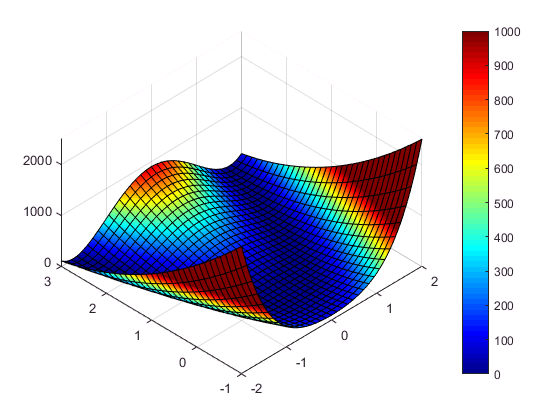

fsurf(f,[-2 2 -1 3])
view([-45 50])
colormap jet
caxis([0,1000])
colorbar

## Motivation

The [“Nonlinear Equations with Analytic Jacobian”](http://www.mathworks.com/help/optim/ug/nonlinear-equations-with-analytic-jacobian.html) example in Optimization Toolbox solves the same problem by using the [`fsolve`](http://www.mathworks.com/help/optim/ug/fsolve.html) function. The workflow shown in that example has two potential sources of errors. You would need to

- Translate the equations for the Rosenbrock function and it's Jacobian from the math form in the text to numeric code.

- Explicitly calculate the Jacobian. For complicated equations, this task is prone to errors.

This example shows that using symbolic math to describe the problem statement and subsequent steps minimizes or even eliminates such errors.

## Rewrite Rosenbrock Function as a System of Nonlinear Equations

First, convert the Rosenbrock function `f` to a system of nonlinear equations `F` , where `F` is a gradient of `f` .

clear
n = 64;
x = sym('x',[n,1]);
f = sum(100*(x(2:2:n)-x(1:2:n).^2).^2 + (1-x(1:2:n)).^2);
F = gradient(f,x);

Show the first 10 equations:

F(1:10)

$$ans = \left(\begin{array}{c} 2\,x_{1}-400\,x_{1}\,\left(x_{2}-{x_{1}}^{2}\right)-2\\ 200\,x_{2}-200\,{x_{1}}^{2}\\ 2\,x_{3}-400\,x_{3}\,\left(x_{4}-{x_{3}}^{2}\right)-2\\ 200\,x_{4}-200\,{x_{3}}^{2}\\ 2\,x_{5}-400\,x_{5}\,\left(x_{6}-{x_{5}}^{2}\right)-2\\ 200\,x_{6}-200\,{x_{5}}^{2}\\ 2\,x_{7}-400\,x_{7}\,\left(x_{8}-{x_{7}}^{2}\right)-2\\ 200\,x_{8}-200\,{x_{7}}^{2}\\ 2\,x_{9}-400\,x_{9}\,\left(x_{10}-{x_{9}}^{2}\right)-2\\ 200\,x_{10}-200\,{x_{9}}^{2} \end{array}\right)$$

 To match the intermediate results shown in the Optimization Toolbox [example](http://www.mathworks.com/help/optim/ug/nonlinear-equations-with-analytic-jacobian.html), use the same form of `F`.

F(1:2:n) = simplify(F(1:2:n) + 2*x(1:2:n).*F(2:2:n));
F(1:2:n) = -F(1:2:n)/2;
F(2:2:n) = F(2:2:n)/20;

Now the systems of equations are identical:

F(1:10)

$$ans = \left(\begin{array}{c} 1-x_{1}\\ 10\,x_{2}-10\,{x_{1}}^{2}\\ 1-x_{3}\\ 10\,x_{4}-10\,{x_{3}}^{2}\\ 1-x_{5}\\ 10\,x_{6}-10\,{x_{5}}^{2}\\ 1-x_{7}\\ 10\,x_{8}-10\,{x_{7}}^{2}\\ 1-x_{9}\\ 10\,x_{10}-10\,{x_{9}}^{2} \end{array}\right)$$

## Calculate Jacobian of Matrix Representing the System of Equations

Use [`jacobian`](http://www.mathworks.com/help/symbolic/jacobian.html) to calculate the Jacobian of `F` . This function calculates the Jacobian symbolically, thus avoiding errors associated with numerical approximations of derivatives.

JF = jacobian(F,x);

Show the first 10 rows and columns of the Jacobian matrix.

JF(1:10,1:10)

$$ans = \left(\begin{array}{cccccccccc} -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ -20\,x_{1} & 10 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -20\,x_{3} & 10 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -20\,x_{5} & 10 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -20\,x_{7} & 10 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -20\,x_{9} & 10 \end{array}\right)$$

Most of the elements of the Jacobian matrix `JF` are zeros. Nevertheless, when you convert this matrix to a [MATLAB function](http://www.mathworks.com/help/symbolic/matlabfunction.html), the result is a dense numeric matrix. Often, operations on sparse matrices are more efficient than the same operations on dense matrices.

Therefore, to create efficient code, convert only the nonzero elements of `JF` to a symbolic vector before invoking matlabFunction. `is` and `js` represent the sparsity pattern of `JF`.

[is,js] = find(JF);
JF = JF(JF~=0);

## Convert System of Equations and Jacobian to a MATLAB function

The system of equations `F` , representing the Rosenbrock function, is a symbolic matrix that consists of symbolic expressions. To be able to solve it with the `fsolve` function, convert this system to a [MATLAB function](http://www.mathworks.com/help/symbolic/matlabfunction.html). At this step, it is convenient to convert both `F` and its Jacobian,`JF` , to a single file-based MATLAB function, `FJFfun`. In principle, this allows `F` and `JF` to reuse variables. Alternatively, you can convert them to individual MATLAB functions.

matlabFunction([F;JF],'var',x,'file','FJFfun');

`FJFfun` accepts variables as a list, but `fsolve` expects a vector of variables. The function `genericObj` converts the vector to a list. Anonymous function `bananaObj` is defined to fix argument values for `genericObj`. Note the use of the sparsity pattern in the function `genericObj`. Further note that this approach of using `FJFfun` and `genericObj` together is not tied to the particular expression represented by `F` and can be used as is for any `F`.

bananaobj = @(y) genericObj(y,@FJFfun,is,js)

bananaobj =     @(y)genericObj(y,@FJFfun,is,js)


help genericObj


No help found for genericObj.m.



## Use fsolve to Numerically Solve the System of Nonlinear Equations

Use `fsolve` for the system of equations, converted to MATLAB function. Use the starting point *x(i) = –1.9* for the odd indices, and *x(i) = 2* for the even indices. Set `'Display'` to`'iter'` to see the solver's progress. Set `'Jacobian'` to `'on'` to use the Jacobian defined in` bananaobj`.

x0(1:n,1) = -1.9;
x0(2:2:n,1) = 2;
options = optimoptions(@fsolve,'Display','iter','Jacobian','on');
[sol1,Fsol,exitflag,output,JAC] = fsolve(bananaobj,x0,options);


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1         8563.84                           615               1


     1          2         3093.71              1            329               1


     2          3         225.104            2.5           34.8             2.5


     3          4          212.48           6.25           34.1            6.25


     4          5          212.48           6.25           34.1            6.25


     5          6         102.771         1.5625           6.39            1.56


     6          7         102.771        3.90625           6.39            3.91


     7          8         87.7443       0.976563           2.19           0.977


     8          9         74.1426        2.44141           6.27            2.44


     9         10         74.1426        2.44141           6.27            2.44


    10         11          52.497       0.610352           1.52            0.61


    11         12         41.3297        1.52588           4.63            1.53


    12         13         34.5115        1.52588           6.97            1.53


    13         14         16.9716        1.52588           4.69            1.53


    14         15         8.16797        1.52588           3.77            1.53


    15         16         3.55178        1.52588           3.56            1.53


    16         17         1.38476        1.52588           3.31            1.53


    17         18        0.219553        1.16206           1.66            1.53


    18         19               0      0.0468565              0            1.53

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



## Use vpasolve to Numerically Solve the System of Nonlinear Equations

The system of nonlinear equations, `F`, can be alternatively solved with the `vpasolve` function, which is a numeric solver available in Symbolic Math Toolbox. A key difference between` vpasolve` and `fsolve` is that `fsolve` uses double-precision arithmetic to solve the equations, whereas `vpasolve` uses [variable-precision arithmetic](http://www-test1.mathworks.com/help/symbolic/vpa.html) and therefore, lets you control the accuracy of computations.

sol2 = vpasolve(F);

If you assign the solution of a system of equations to one variable, `sol2`, then `vpasolve`returns the solutions in form of a structure array. You can access each solution (each field of the structure array):

sol2.x1

$$ans = 1.0$$

You also can convert `sol2` to a symbolic vector, and then access a range of the solutions. For example, display the 5th to 25th solutions:

for k=(1:64)
  sol2_array(k) = sol2.(char(x(k)));
end
sol2_array(5:25)

$$ans = \left(\begin{array}{ccccccccccccccccccccc} 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 & 1.0 \end{array}\right)$$

# Helper Functions

function [F,J] = genericObj(x,FJFfun,is,js)
% genericObj takes as input, vector x, Function and Jacobian evaluation 
% function handle FJFfun, and sparsity pattern is,js and returns as output,
% the numeric values of the Function and Jacobian: F and Jfunction 
% FJs(1:length(x)) is the numeric vector for the Function
% FJs(length(x)+1:end) is the numeric vector for the non-zero entries of the Jacobian

xcell = num2cell(x);
FJs = FJFfun(xcell{:});
F = FJs(1:length(x));
J = sparse(is,js,FJs(length(x)+1:end));

end

*Copyright *© *2016 The MathWorks, Inc.*